% This script generates Figure 2 in the main manuscript, characterizing behavioral metrics of spatial cognitive maps.
% Four raw behavioral measures (PlE, AR, AE, PE) are visualized across repetitions,
% LMM estimates of two composite scores (SMA and NE) across repetition and runs


%% =========================
% Load and reshape behavioral data
% =========================

load('Figure_codes/Figure_data/Behavior_LMM.mat');

% Each variable is reshaped to [subjects × repetitions]
PlE = reshape(behavior.PlE, 6, 43)'; % Placement error (vm)
AR  = reshape(behavior.AR,  6, 43)'; % Accuracy rate
PE  = reshape(behavior.PE,  6, 43)'; % Path efficiency
AE  = reshape(behavior.AE,  6, 43)'; % Angular error


%% =========================
% Visualization parameters
% =========================

font_size  = 12;
line_width = 1;
marker_size = 5;
tick_length = 0.02;

% Color definitions
colors = [218 227 243]/255;

## ---- Panel A: PlE & AR ----

figure('Color','w');
subplot(2,2,1); hold on;

% Left axis: Placement error
yyaxis left
lineplot_columns(1:3, PlE_reshape(:,1:3), ...
    'color',[0 0 0],'markerfacecolor',[.5 .5 .5], ...
    'w',line_width,'markersize',marker_size);
lineplot_columns([4.2 5.2 6.2], PlE_reshape(:,4:6), ...
    'color',[0 0 0],'markerfacecolor',[.5 .5 .5], ...
    'w',line_width,'markersize',marker_size);

ylim([20 80]); yticks([20 40 60 80]);
set(gca, 'YColor', [0 0 0]);

% Right axis: Accuracy rate (%)
yyaxis right
lineplot_columns(1:3, AR_reshape(:,1:3)*100, ...
    'color',[0.5 0.5 0.5],'markerfacecolor',[0.5 0.5 0.5], ...
    'w',line_width,'markersize',marker_size);
lineplot_columns([4.2 5.2 6.2], AR_reshape(:,4:6)*100, ...
    'color',[0.5 0.5 0.5],'markerfacecolor',[0.5 0.5 0.5], ...
    'w',line_width,'markersize',marker_size);
ylim([0 60]); yticks([0 20 40 60]);
set(gca, 'YColor', [0.5 0.5 0.5]);
xlim([0.6,6.7]);xticks([1 2 3 4.2 5.2 6.2])
set(gca,'XTickLabel',{'1','2','3','1','2','3'});
format_axis(font_size, line_width, tick_length,[0.95 1 1]);


## ---- Panel B: AE & PE ----


subplot(2,2,2); hold on;

% Left axis: Angular error
yyaxis left
lineplot_columns(1:3, AE_reshape(:,1:3), ...
    'color',[0 0 0],'markerfacecolor',[.5 .5 .5], ...
    'w',line_width,'markersize',marker_size);
lineplot_columns([4.2 5.2 6.2], AE_reshape(:,4:6), ...
    'color',[0 0 0],'markerfacecolor',[.5 .5 .5], ...
    'w',line_width,'markersize',marker_size);
ylim([20 80]); yticks([20 40 60 80]);
set(gca, 'YColor', [0 0 0]);


% Right axis: Path efficiency (%)
yyaxis right
lineplot_columns(1:3, PE_reshape(:,1:3)*100, ...
    'color',[0.5 0.5 0.5],'markerfacecolor',[0.5 0.5 0.5], ...
    'w',line_width,'markersize',marker_size);
lineplot_columns([4.2 5.2 6.2], PE_reshape(:,4:6)*100, ...
    'color',[0.5 0.5 0.5],'markerfacecolor',[0.5 0.5 0.5], ...
    'w',line_width,'markersize',marker_size);
ylim([20 80]); yticks([20 40 60 80]);
set(gca, 'YColor', [0.5 0.5 0.5]);


xlim([0.6,6.7]);xticks([1 2 3 4.2 5.2 6.2])
set(gca,'XTickLabel',{'1','2','3','1','2','3'});
format_axis(font_size, line_width, tick_length,[0.95 1 1]);

## ---- Panel C: SMA LMM ----


% fixed effect of object repetition
subplot(2,2,3); hold on;

T = LMM_fixed_SMA_top;
x = T.x; fit = T.fit;
lower = T.lower; upper = T.upper;

fill([x; flipud(x)], [upper; flipud(lower)], ...
     color,'EdgeColor','none','FaceAlpha',0.5);
plot(x,fit,'k-','LineWidth',line_width*2);

set(gca,'FontSize',font_size,'LineWidth',line_width, ...
    'TickDir','out','TickLength',[tick_lengh tick_lengh]);
xlim([0.95 3.05]); ylim([-1 1]);
xticks([1 2 3]); yticks([-1 0 1]);

format_axis(font_size, line_width, tick_length,[1 1 1]);

## ---- Panel D: NE LMM ----

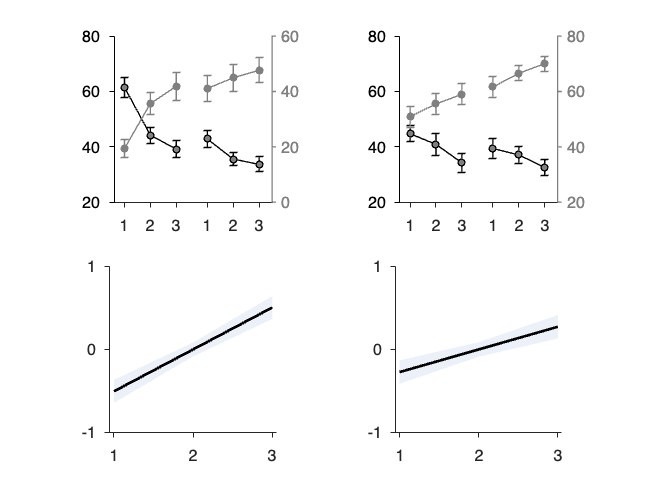

%fixed effect of object repetition
subplot(2,2,4); hold on;
T = LMM_fixed_NE_top;
x = T.x; fit = T.fit;
lower = T.lower; upper = T.upper;

fill([x; flipud(x)], [upper; flipud(lower)], ...
     color,'EdgeColor','none','FaceAlpha',0.5);
plot(x,fit,'k-','LineWidth',line_width*2);

xlim([0.95 3.05]); ylim([-1 1]);
xticks([1 2 3]); yticks([-1 0 1]);

format_axis(font_size, line_width, tick_length,[1 1 1]);

## ---- fixed effect of run ----

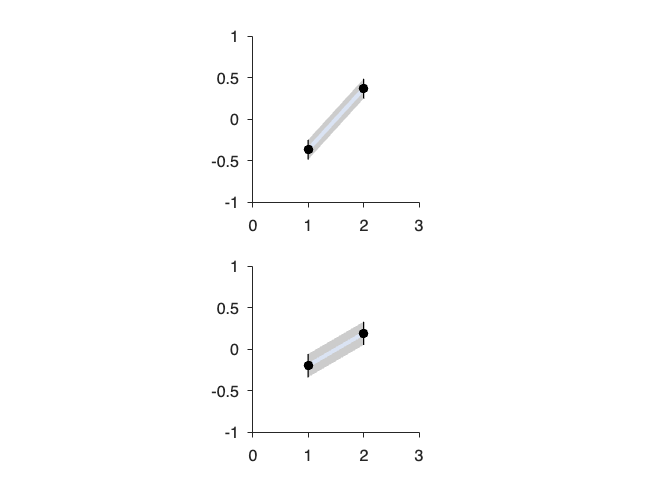


figure()
subplot(2,1,1)
T = LMM_fixed_SMA_block;
x = T.x; fit = T.fit;
lower = T.lower; upper = T.upper;
error = fit - lower;
color = [218 227 243]/255;
hold on
fill([x; flipud(x)], [upper; flipud(lower)], ...
     [0.6 0.6 0.6],'EdgeColor','none','FaceAlpha',0.5);
plot(x,fit,'-','Color',color,'LineWidth',line_width*3);

errorbar(x,fit, error, ...
    'ko', ...
    'MarkerFaceColor','k', ...
    'LineWidth', line_width, ...
    'CapSize', 0);
xlim([0 3]);ylim([-1 1]);
format_axis(font_size, line_width, tick_length,[1 1 1]);


subplot(2,1,2)
T = LMM_fixed_NE_block;
x = T.x; fit = T.fit;
lower = T.lower; upper = T.upper;
error = fit - lower;
hold on
fill([x; flipud(x)], [upper; flipud(lower)], ...
     [0.6 0.6 0.6],'EdgeColor','none','FaceAlpha',0.5);
plot(x,fit,'-','Color',color,'LineWidth',line_width*3);

errorbar(x,fit, error, ...
    'ko', ...
    'MarkerFaceColor','k', ...
    'LineWidth', line_width, ...
    'CapSize', 0);
hold off
xlim([0 3]);ylim([-1 1]);
format_axis(font_size, line_width, tick_length,[1 1 1]);

function format_axis(fs, lw, tick_len, scale)
% Standard axis formatting
% scale: optional aspect ratio [x y z], default = [1 1 1]

    if nargin < 4 || isempty(scale)
        scale = [1 1 1];
    end

    set(gca, ...
        'FontSize', fs, ...
        'LineWidth', lw, ...
        'TickDir', 'out', ...
        'TickLength', [tick_len tick_len]);

    pbaspect(scale);
    box off;
end
